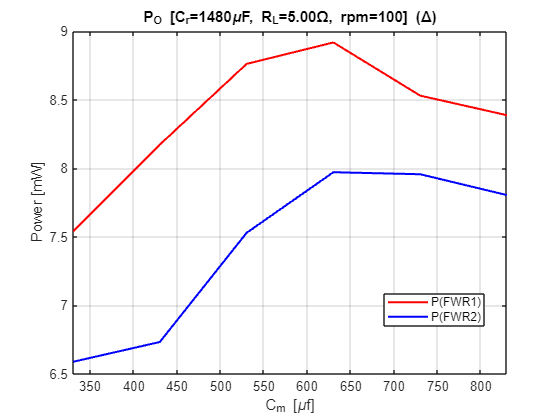


% Dati misurati (D1_100rpm.csv, D2_100rpm.csv - tabella "R = 5 Ohm"):
% sweep del condensatore di compensazione C_m, R_L e rpm fissi, per i due bridge FWR-Delta.

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 5;            % Ohm - carico fisso durante lo sweep
rpm_b1 = 100;       % rpm fisso durante lo sweep

C_L = [330 430 530 630 730 830]*1e-6;   % F - condensatore di compensazione C_m (asse x)

Po_b1_mW = [75.396 81.715 87.602 89.164 85.290 83.861];
Pi_b1_mW = [318.035 328.475 339.414 339.715 333.373 331.237];

Po_b2_mW = [65.889 67.332 75.288 79.707 79.560 78.039];
Pi_b2_mW = [313.694 316.066 334.677 338.943 338.769 330.931];

P_real_b1 = Po_b1_mW/1000;
P_real_b2 = Po_b2_mW/1000;

P_in_b1 = Pi_b1_mW/1000;
P_in_b2 = Pi_b2_mW/1000;


figure;
plot(C_L*1e6, P_real_b1*1000/10, 'r-', 'LineWidth', 1.5);hold on;
plot(C_L*1e6, P_real_b2*1000/10, 'b-', 'LineWidth', 1.5);
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega, rpm=%.0f] (FWR-\\Delta)', C_r*1e6,R_L,rpm_b1));
xlabel('C_m [\muf]');
ylabel('Power [mW]');
xlim([min(C_L*1e6), max(C_L)*1e6]);
legend(["P(FWR1)", "P(FWR2)"], "Location", "best")
hold off;

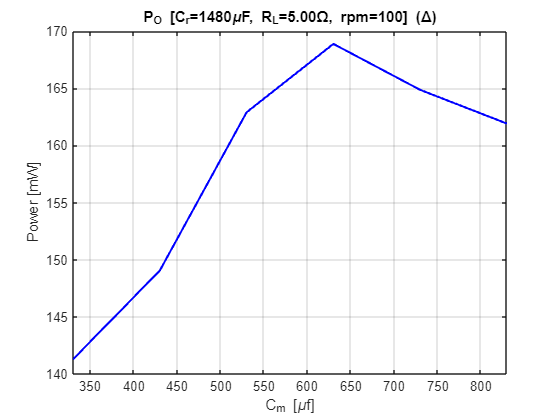



figure;
plot(C_L*1e6, (P_real_b1+P_real_b2)*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega, rpm=%.0f] (FWR-\\Delta)', C_r*1e6,R_L,rpm_b1));
xlabel('C_m [\muf]');
ylabel('Power [mW]');
xlim([min(C_L*1e6), max(C_L)*1e6]);
hold off;